clear;clc;

% load parameters
par = importdata('par_scg.txt');
par = par.data;

% initial values
y0 = zeros(3, 1);
y0(1) = 1;
y0(3) = 100;

tmax = 100;
tspan = 0:0.1:tmax;

[~, y] = ode45(@ODE_SCG, tspan, y0, [], par);

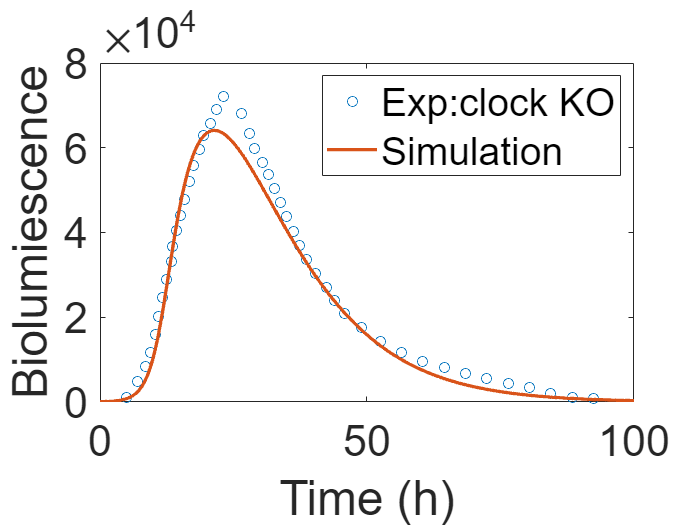

biolu_data_ko = importdata('biolu_data_ko.txt');

figure; hold on; set(gca,'Fontsize',26); box on;
scatter(biolu_data_ko(:, 1), biolu_data_ko(:, 2));
plot(tspan, y(:, 3), 'LineWidth', 2);
xlabel('Time (h)'); ylabel('Biolumiescence');
legend('Exp:clock KO', 'Simulation');